# Script for reproducing data for paper figure 3

This script should reproduce the data used in figure 3 of our paper, it reproduces only the Matlab data of the new optimized model.

Run times measured on a Intel® Core™ i9-10980XE and MATLAB® 2021a

Total run time less than 2 min.

Prerequisites:

Have the Model_Nair_2016 model (found at https://github.com/jpgsantos/Model_Nair_2016) inside the Subcellular_workflow/Matlab/Model folder

Add the Subcellular_workflow folder and all subfolders to the Matlab path

Run the script with Subcellular_workflow as your main matlab folder

## Figure 5 B and C

### Run the model with optimized parameters

Run time ~= 1 minute (user input is needed and might afect this time)

Copy the settings file to be used in this analysis from the "Subcellular_workflow\Code for paper figures\Reproduce paper figure 3" into the Subcellular_workflow\Matlab\Model\Model_Nair_2016\Settings" folder.

% copyfile("../Subcellular_workflow/Code for paper figures/Figure 7/Nair_2016_optimized_fig7.m","../Subcellular_workflow/Matlab/Model/Model_Nair_2016/Settings/Nair_2016_optimized_fig7.m")

Note: If you have customized folder names please change the above code accordingly or manually copy the settings file.

In the command window select the following:

Model_Nair_2016 (The folder of the model)

Diagnostics (The analysis to be performed)

Nair_2016_optimized_fig3.m (The settings file to be used)

% Run_main

### Save the needed files for the plots or copy them from the model folder

Run time ~= 1.5 seconds

% copyfile("../Subcellular_workflow/Matlab/Model/Model_Nair_2016/Data/model_Nair_2016_optimized.mat","../Subcellular_workflow/Code for paper figures/Figure 7/model_Nair_2016_optimized_fig7.mat")

If this line fails check the paths or manually copy the "model_Nair_2016_optimized.mat" file from Matlab/Model/"Model folder name"/Data into the folder of this script and rename it to model_Nair_2016_optimized_fig3.mat

### Run the optimized model with dopamine input at different times

Run time ~= 25 seconds

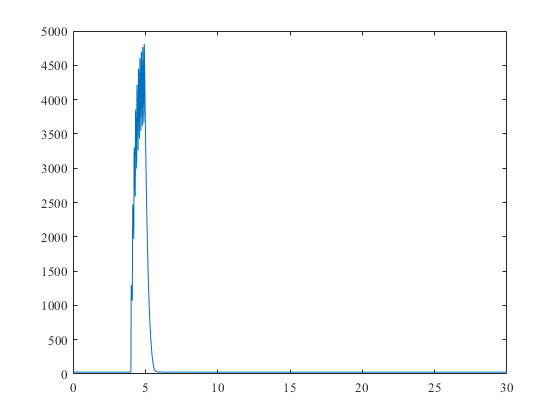

f_Reproduce_new_data_fig7_C("../Subcellular_workflow/Code for paper figures/Figure 7/")